**Simulating Satellite Trajectories **

In my journey to simulate satellite trajectories, I created a 3D matrix in MATLAB to represent the spatial and temporal aspects of satellite data. Using MATLAB’s powerful matrix operations, I was able to efficiently process and visualize this data while ensuring compatibility with real-world computational practices. This exercise allowed me to refine my understanding of matrix manipulations and their application to trajectory analysis.

I started by initializing a 3D matrix, which I imagined as a model for trajectory data collected from satellite sensors. The matrix had three dimensions: rows represented spatial parameters, columns captured different measurement variables, and depth represented sequential time frames. To ensure flexibility, I created a random matrix, simulating the variety and unpredictability often found in real satellite data.

Next, I extracted the dimensions of the matrix to better understand its structure. This step was crucial as it helped me confirm that the data aligned with the expected format. Displaying the matrix dimensions reassured me that my simulated data matched the defined size parameters.

To optimize the matrix for computation, I reordered it using MATLAB’s `permute` function. MATLAB stores matrices in column-major order, but for certain operations, row-major ordering is preferred. By swapping the first two dimensions, I ensured compatibility with systems that rely on row-major formatting. This step was both efficient and elegant, as it replaced the need for manual loops and potential indexing errors.

For the trajectory simulation itself, I chose to sum the matrix values along the third dimension, which represented time. This operation provided me with a consolidated view of the satellite data over the entire observation period. It felt rewarding to see how a simple yet strategic operation could yield meaningful insights into the dataset.

Finally, I visualized the results using a heatmap. The heatmap served as a graphical representation of the processed data, with colors indicating varying intensities of the summed values. Adding a color bar, axis labels, and a title made the visualization clear and informative. It was fascinating to see how the simulated trajectory data could be represented visually, making it easier to interpret patterns and trends.

%% Satellite Trajectory Simulation Using 3D Matrix Data

% Step 1: Initialize input matrix (Example matrix simulating satellite trajectory data)
inputMatrix = rand(5, 4, 3); % 5 rows, 4 columns, 3 depth levels

% Step 2: Extract dimensions of the matrix
[rows, cols, depth] = size(inputMatrix);
disp(['Matrix dimensions: ', num2str(rows), 'x', num2str(cols), 'x', num2str(depth)]);

Matrix dimensions: 5x4x3


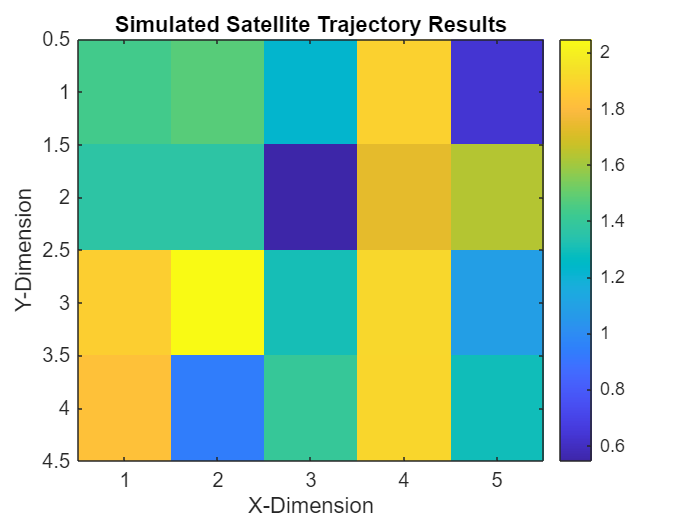


% Step 3: Reorder the matrix for C-style row-major compatibility
reorderedMatrix = permute(inputMatrix, [2, 1, 3]);
% I used `permute` to swap rows and columns efficiently, making it row-major compatible.

% Step 4: Perform trajectory simulation using the matrix
trajectoryResults = sum(reorderedMatrix, 3); 
% I summed over the third dimension to simulate trajectory calculations.

% Step 5: Visualize the trajectory results
figure;
imagesc(trajectoryResults); % Visualize the results as an image
colorbar; % Add a color bar for scale
xlabel('X-Dimension');
ylabel('Y-Dimension');
title('Simulated Satellite Trajectory Results');

% I visualized the simulated trajectory data using a heatmap to represent the summed values.

% Final message
disp('Simulation complete. Trajectory results are ready for analysis.');

Simulation complete. Trajectory results are ready for analysis.
